# SISTEMES D'EQUACIONS NO LINEALS

## Gràfiques 

fplot(@(t)exp(-t.^2),[-3,3]),
title('campana de Gauss')

clearvars
fimplicit(@(x,y)x-sin(x+y),'r',[-10,10])
hold on
fimplicit(@(x,y)y-cos(x-y),[-10,10])
grid on
hold off

xlim([-1.5 2.5])
ylim([-4 4])
clf

## Mètodes de la iteració simple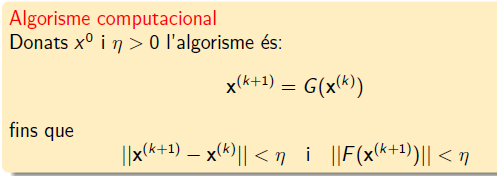

Z=[1;1]
G=@(x,y)[sin(x+y); cos(x-y)]
JG=@(x,y)[cos(x+y) cos(x+y); -sin(x-y) sin(x-y)]   % Teorema convergència
control_apriori = norm(JG(1,1),'inf')
if control_apriori >= 1
    error('mètode divergent')
    return
else
    for k=1:5
    Z=G(Z(1),Z(2))
    end
end

clearvars;
Z=[1;1], k=0;
F=@(x,y)[x-sin(x+y); y-cos(x-y)];
G=@(x,y)[sin(x+y); cos(x-y)];
JG=@(x,y)[cos(x+y) cos(x+y); -sin(x-y) sin(x-y)];   % Teorema convergència
control_apriori = norm(JG(1,1),'inf')
tolF = 1; tolZ = 1;
while (tolF > 1e-6 || tolZ > 1e-6) && (control_apriori < 1) && (k < 10)
    Zold=Z;
    Z=G(Z(1),Z(2));
    tolF=norm(F(Z(1),Z(2)),'inf');
    tolZ=norm(Z-Zold,'inf');
    k=k+1;    
end
disp(['la solucio és = ',num2str(Z')])
disp(['tolF és = ',num2str(tolF)])
disp(['tolZ és = ',num2str(tolZ)])
disp(['iteracions = ',num2str(k-1)])

## MÈTODE DE NEWTON i variants

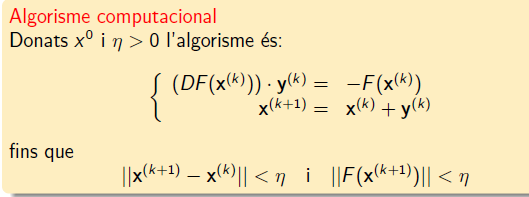

clearvars;
Z=[1;1]; k=0; 
F=@(x,y)[x-sin(x+y); y-cos(x-y)];
JF=@(x,y)[1-cos(x+y) -cos(x+y); -sin(x-y) 1-sin(x-y)];   
tolF = 2; tolZ = 1; p(1)=0;
while (tolF > 1e-6 || tolZ > 1e-6) && (k < 10)
     tolF_old=tolF;
     A = JF(Z(1),Z(2)); b=-F(Z(1),Z(2)); Y=A\b;
     Z = Z + Y;
     k = k+1
     tolF=norm(F(Z(1),Z(2)),'inf')
     tolZ=norm(Y,'inf');
     p(k)=log(tolF)/log(tolF_old);   % convergeix a 2??
end

k = 1

tolF = 0.0021

k = 2

tolF = 1.1497e-04

k = 3

tolF = 3.2768e-06

k = 4

tolF = 1.0339e-07

k = 5

tolF = 3.2520e-09

#### Mètode de Newton modificat

clearvars;
Z=[1;1]; k=0; 
F=@(x,y)[x-sin(x+y); y-cos(x-y)];
JF=@(x,y)[1-cos(x+y) -cos(x+y); -sin(x-y) 1-sin(x-y)];   
tolF = 2; tolZ = 1; p(1)=0;
A = JF(Z(1),Z(2));    % matriu fixada per totes les iteracions
while (tolF > 1e-6 || tolZ > 1e-6) && (k < 10)
     tolF_old=tolF;
     b=-F(Z(1),Z(2)); Y=A\b;
     Z = Z + Y;
     k = k+1
     tolF=norm(F(Z(1),Z(2)),'inf')
     tolZ=norm(Y,'inf');
     p(k)=log(tolF)/log(tolF_old);   % convergeix a 2??
end

k = 1

tolF = 0.0021

k = 2

tolF = 1.6761e-04

k = 3

tolF = 1.4245e-05

k = 4

tolF = 9.9726e-07

k = 5

tolF = 1.1578e-07

#### Mètode de Jacobi

clearvars;
Z=[1;1]; k=0; 
F=@(x,y)[x-sin(x+y); y-cos(x-y)];
JF=@(x,y)[1-cos(x+y) -cos(x+y); -sin(x-y) 1-sin(x-y)];   
tolF = 2; tolZ = 1; p(1)=0;
    % matriu fixada per totes les iteracions
while (tolF > 1e-6 || tolZ > 1e-6) && (k < 10)
     tolF_old=tolF;
     A = diag(diag(JF(Z(1),Z(2))));
     b=-F(Z(1),Z(2)); Y=A\b;
     Z = Z + Y;
     k = k+1
     tolF=norm(F(Z(1),Z(2)),'inf')
     tolZ=norm(Y,'inf');
     p(k)=log(tolF)/log(tolF_old);   % convergeix a 2??
end

k = 1

tolF = 0.0021

k = 2

tolF = 6.8302e-04

k = 3

tolF = 3.1843e-05

k = 4

tolF = 1.0618e-05

k = 5

tolF = 4.9306e-07

k = 6

tolF = 1.6442e-07

#### Mètode de Gauss-Seidel

clearvars;
Z=[1;1]; k=0; 
F=@(x,y)[x-sin(x+y); y-cos(x-y)];
JF=@(x,y)[1-cos(x+y) -cos(x+y); -sin(x-y) 1-sin(x-y)];   
tolF = 2; tolZ = 1; p(1)=0;
    % matriu fixada per totes les iteracions
while (tolF > 1e-6 || tolZ > 1e-6) && (k < 10)
     tolF_old=tolF;
     A = tril(JF(Z(1),Z(2)));
     b=-F(Z(1),Z(2)); Y=A\b;
     Z = Z + Y;
     k = k+1
     tolF=norm(F(Z(1),Z(2)),'inf')
     tolZ=norm(Y,'inf');
     p(k)=log(tolF)/log(tolF_old);   % convergeix a 2??
end

k = 1

tolF = 0.0021

k = 2

tolF = 6.5347e-04

k = 3

tolF = 6.9328e-05

k = 4

tolF = 1.9305e-05

k = 5

tolF = 2.4454e-06

k = 6

tolF = 5.5987e-07

k = 7

tolF = 8.4403e-08